clear;

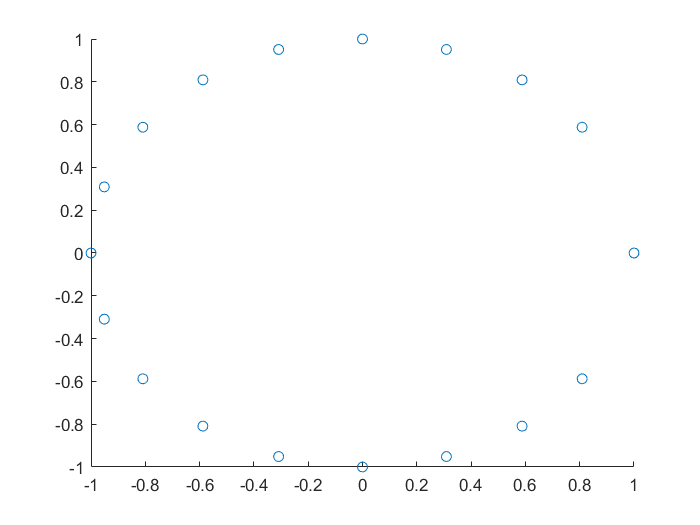

%圆形数据生成
count = 20;
theta = 0:(2*pi/count):2*pi;
 theta(end)=[];
%  theta(1)=[];theta(10)=[];
% theta(1)=2*pi/40;theta(19)=2*pi-2*pi/40;
theta(end)=[];theta(2)=[];
Points = [cos(theta'),sin(theta')];
Normals = Points;
scatter(Points(:,1),Points(:,2),'o');

% hold on
% scatter(Points(1,1),Points(1,2),'x');
% hold on
% scatter(Points(18,1),Points(18,2),'x');
% hold off
n = length(theta);

k = 6*ones(n,1);
s = -0.5;
% 生成kd树
kdtree = KDTreeSearcher(Points);
boxlength=norm(min(Points)-max(Points));
% 计算各点支撑半径
SupportSizes = zeros(n,1);

distlist=SupportSizes;
mindist=distlist;
for i=1:n
    [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
    SupportSizes(i) = max(dists);
    mindist(i)=(dists(2));
    distlist(i)=(sum(dists)/k(i))/SupportSizes(i);
end
maxSupportSize = max(SupportSizes);
% 生成局部坐标系，各点二次曲线
[Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);

for i=1:n
    Err(i)=sqrt(CalErr(Points(i,1),Points(i,2),Points,Bases,Hparas, ...
        kdtree,maxSupportSize,SupportSizes));
end


% 设置拟合系数
ApproxArgs = zeros(n,1);



meanerr=mean(Err);
maxerr=max(Err);
minerr=min(Err);
x=min(Points(:,1));xx=max(Points(:,1));
y=min(Points(:,2));yy=max(Points(:,2));
boxlength=sqrt((xx-x)^2+(yy-y)^2);
[d,dn]=CalSumd(Points,x,xx,y,yy);
d=d/dn;
c=2*d/boxlength;
x=zeros(n,1);



for i=1:n
    ApproxArgs(i) =c;
    [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
%     indices(1)=[];
%     maxerr=max(Err(indices));
%     minerr=min(Err(indices));
    if(Err(i)-meanerr>1e-7)
        x(i)=(Err(i)-meanerr)/(maxerr-minerr);
        ApproxArgs(i)=c/(1+x(i));
    elseif(Err(i)-meanerr<-1e-7)
        x(i)=(Err(i)-meanerr)/(maxerr-minerr);
        ApproxArgs(i)=c*(1-x(i));
    end


%     ApproxArgs(i) = c;
end






% 
% for i=1:n
%         ApproxArgs(i)=1;
% end
% 计算C值
C = zeros(n,1);
for i=1:n
    [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
    indices = indices{1};
    dists = dists{1};
    valsum = 0;
    rbfsum = 0;
    H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
    for j=1:length(indices)
        if dists(j)>=SupportSizes(indices(j))
            continue
        end
        %Wendland part
        value = rbf_wend(dists(j)/SupportSizes(indices(j)));
        %shepard part
%         value = rbf_shp(dists(j)/SupportSizes(indices(j)));
%         if(value==inf)
%             valsum=H(j);
%             rbfsum=1;
%             break;
%         end
        %Our method
        if dists(j)<1e-7 && ApproxArgs(indices(j))<1e-7 
            valsum = C(indices(j))+H(j);
            rbfsum = 1;
            break;
        end
        value = rbf(dists(j)/SupportSizes(indices(j)),ApproxArgs(indices(j)),s);
%         
        valsum = valsum - H(j)*value;
        rbfsum = rbfsum + value;
    end
    C(i) = valsum/rbfsum;
end

% % 画隐曲线
f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize, ...
    SupportSizes,ApproxArgs,s,C,1));
% area = [-1,1,-1,1];
% fp = fimplicit(f, area);
% % 
% hold on;
% scatter(Points(:,1),Points(:,2),'*');

%插值点误差
F1=zeros(length(theta),1);
for j=1:length(theta)
    F1(j)=f(Points(j,1),Points(j,2));
end
Maxe1=max(abs(F1))

Maxe1 = 5.3884e-04

Meane1=mean(abs(F1))

Meane1 = 1.6931e-04

%测试点误差
res = 1000;
theta = 0:(2*pi/res):2*pi;
F=zeros(length(theta),1);
respoints = [cos(theta)',sin(theta)'];
for j=1:length(theta)
    F(j)=f(respoints(j,1),respoints(j,2));
end
Maxe2=max(abs(F))

Maxe2 = 0.0087

Meane2=mean(abs(F))

Meane2 = 0.0012

% % 计算C值
% C = zeros(n,1);
% for i=1:n
%     [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
%     indices = indices{1};
%     dists = dists{1};
%     valsum = 0;
%     rbfsum = 0;
%     H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
%     for j=1:length(indices)
%         if dists(j)>=SupportSizes(indices(j))
%             continue
%         end
%         %Wendland part
%         value = rbf_wend(dists(j)/SupportSizes(indices(j)));
%         %shepard part
% %         value = rbf_shp(dists(j)/SupportSizes(indices(j)));
% %         if(value==inf)
% %             valsum=H(j);
% %             rbfsum=1;
% %             break;
% %         end
%         %Our method
% %         if dists(j)<1e-7 && ApproxArgs(indices(j))<1e-7 
% %             valsum = C(indices(j))+H(j);
% %             rbfsum = 1;
% %             break;
% %         end
% %         value = rbf(dists(j)/SupportSizes(indices(j)),ApproxArgs(indices(j)),s);
%         
%         valsum = valsum - H(j)*value;
%         rbfsum = rbfsum + value;
%     end
%     C(i) = valsum/rbfsum;
% end

% % 画隐曲线
% hold on
% g = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,2));
% area = [-1,1,-1,1];
% fp = fimplicit(g, area);
% % 
% % hold off;


% % %A series test
% count = 10:5:100;
% theta=cell(length(count),1);PPoints=theta;NNormals=PPoints;
% nn=PPoints;
% for i=1:length(count)
%     theta{i} = 0:(2*pi/count(i)):2*pi;
%     PPoints{i} = [cos(theta{i}'),sin(theta{i}')];
%     NNormals{i} = PPoints{i};
%     nn{i} = length(theta{i});
% end
% 
% 
% Maxtesterror=zeros(length(count),1);
% Meantesterror=zeros(length(count),1);
% 
% for j=1:length(count)
%    Points=PPoints{j};n=nn{j};
%     Normals=NNormals{j};
%     kdtree = KDTreeSearcher(Points);
%     k = 7*ones(n,1);
%     SupportSizes = zeros(n,1);
%     distlist=zeros(n,1);
%     mindist=distlist;
%     for i=1:n
%         [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
%         SupportSizes(i) = max(dists);
%         mindist(i)=dists(2);
%         distlist(i)=(sum(dists)/k(i))/SupportSizes(i);
%     end
%     maxSupportSize = max(SupportSizes);
%     ApproxArgs = zeros(n,1);
%     % 生成局部坐标系，各点二次曲线
%     [Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);
%     meanerr=mean(Err);
%     var=sum((Err-meanerr).^2)/n;
%     meand=mean(distlist);
%     vard=sum((distlist-meand).^2)/n;
%     meanmd=mean(mindist);
%     varmd=sum((mindist-meanmd).^2)/n;
%     %%%计算对应的各个参数
%     c=1;
%     for i1=1:n
%         ApproxArgs(i1) = c;
%         if((mindist(i1)-meanmd)^2>3*varmd)
% %             i1=i
%             x=sqrt((mindist(i1)-meanmd)^2/(3*varmd));
%             if((mindist(i1)-meanmd)<0)
%                 %越稠密，越逼近
%                 ApproxArgs(i1)=c*(x);
%             else
%                  %越稀疏，越插值
%                 ApproxArgs(i1)=c*(1/x);
%             end
%         elseif((distlist(i1)-meand)^2>3*vard)
%             x=sqrt((distlist(i1)-meand)^2/(3*vard));
%             if((distlist(i1)-meand)>0)
%                 ApproxArgs(i1)=c/x;
%             else
%                 ApproxArgs(i1)=c*x;
%             end
%         elseif((Err(i1)-meanerr)^2>3*var)
%             x=sqrt((Err(i1)-meanerr)^2/(3*var));
%             if(Err(i)-meanerr>0)
%                 ApproxArgs(i1)=c/(x);
%             else
%                 ApproxArgs(i1)=c*x;
%             end
%         end
%     end
% 
%     %%%计算对应的各个参数
%     C = zeros(n,1);
%     for i=1:n
%         [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
%         indices = indices{1};
%         dists = dists{1};
%         valsum = 0;
%         rbfsum = 0;
%         H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
%         for j1=1:length(indices)
%             if dists(j1)>=SupportSizes(indices(j1))
%                 continue
%             end
%             %Our method
%             if dists(j1)<1e-7 && ApproxArgs(indices(j1))<1e-7 
%                 valsum = C(indices(j1))+H(j1);
%                 rbfsum = 1;
%                 break;
%             end
%             value = rbf(dists(j1)/SupportSizes(indices(j1)),ApproxArgs(indices(j1)),s);
%         
%             valsum = valsum - H(j1)*value;
%             rbfsum = rbfsum + value;
%         end
%         C(i) = valsum/rbfsum;
%     end
%     f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,1));
%     res = 1000;
%     restheta = 0:(2*pi/res):2*pi;
%     respoints = [cos(restheta)',sin(restheta)'];
%     F=zeros(length(restheta),1);
%     for i=1:length(restheta)
%         F(i)=f(respoints(i,1),respoints(i,2));
%     end
%     error2=abs(F);
%     Maxtesterror(j)=max(error2);
%     Meantesterror(j)=mean(error2);
% end
% 

% Maxtesterror_W=zeros(length(count),1);
% Meantesterror_W=zeros(length(count),1);
% 
% for j=1:length(count)
%    Points=PPoints{j};n=nn{j};
%     Normals=NNormals{j};
%     kdtree = KDTreeSearcher(Points);
%     k = 7*ones(n,1);
%     for i=1:n
%         [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
%         SupportSizes(i) = max(dists);
%     end
%     maxSupportSize = max(SupportSizes);
%     % 生成局部坐标系，各点二次曲线
%     [Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);
%     maxerr=max(Err);
%     minerr=min(Err);
%     %%%计算对应的各个参数
%     C = zeros(n,1);
%     for i=1:n
%         [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
%         indices = indices{1};
%         dists = dists{1};
%         valsum = 0;
%         rbfsum = 0;
%         H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
%         for j1=1:length(indices)
%             if dists(j1)>=SupportSizes(indices(j1))
%                 continue
%             end
%             %Wendland part
%           value = rbf_wend(dists(j1)/SupportSizes(indices(j1)));
%             %shepard part
% %           value = rbf_shp(dists(j)/SupportSizes(indices(j)));
% %           if(value==inf)
% %               valsum=H(j);
% %               rbfsum=1;
% %               break;
% %           end
%             %Our method
% %             if dists(j1)<1e-7 && ApproxArgs(indices(j1))<1e-7 
% %                 valsum = C(indices(j1))+H(j1);
% %                 rbfsum = 1;
% %                 break;
% %             end
% %             value = rbf(dists(j1)/SupportSizes(indices(j1)),ApproxArgs(indices(j1)),s);
% %         
%             valsum = valsum - H(j1)*value;
%             rbfsum = rbfsum + value;
%         end
%         C(i) = valsum/rbfsum;
%     end
%     f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,2));
%     res = 1000;
%     restheta = 0:(2*pi/res):2*pi;
%     respoints = [cos(restheta)',sin(restheta)'];
%     F=zeros(length(restheta),1);
%     for i=1:length(restheta)
%         F(i)=f(respoints(i,1),respoints(i,2));
%     end
%     error2=abs(F);
%     Maxtesterror_W(j)=max(error2);
%     Meantesterror_W(j)=mean(error2);
% end

% figure;
% plot(count,-log10(Maxtesterror),'-o',count,-log10(Meantesterror), '*-','linewidth', 1);
% hold on
% plot(count,-log10(Maxtesterror_W),'-o',count,-log10(Meantesterror_W), '*-','linewidth', 1);
% legend('Max error I','Mean error I','Max error II','Mean error II','Location','Northwest')
% xlabel('count')
% hold off;

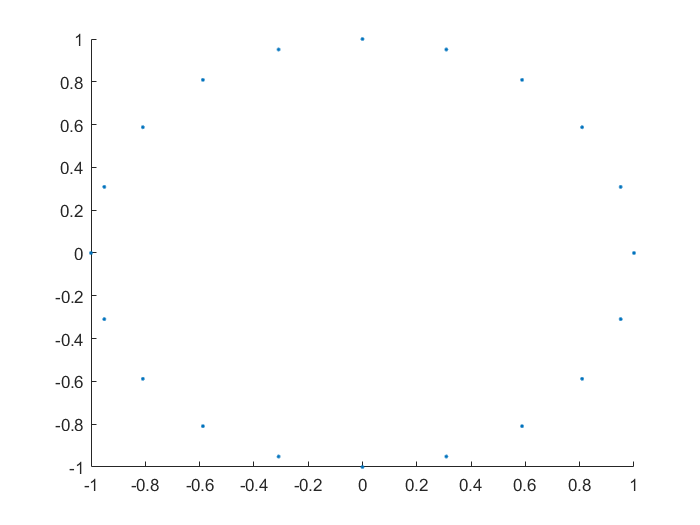

% A series test 2
count = 20;
theta = 0:(2*pi/count):2*pi;
theta(end)=[];
Points = [cos(theta'),sin(theta')];
Normals = Points;
scatter(Points(:,1),Points(:,2),'.');

n = length(theta);

s=-0.5;
a=0:0.1:3;
%a=1;

Maxtesterror=zeros(length(a),1);
Meantesterror=zeros(length(a),1);
MaxIerror=zeros(length(a),1);
MeanIerror=zeros(length(a),1);

for j=1:length(a)
    kdtree = KDTreeSearcher(Points);
  k = 6*ones(n,1);
    SupportSizes = zeros(n,1);
    distlist=zeros(n,1);
    mindist=distlist;
    for i=1:n
        [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
        SupportSizes(i) = max(dists);
        mindist(i)=dists(2);
        distlist(i)=(sum(dists)/k(i))/SupportSizes(i);
    end
    maxSupportSize = max(SupportSizes);
    ApproxArgs = zeros(n,1);
    % 生成局部坐标系，各点二次曲线
    [Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);
    %%%计算对应的各个参数
    c=a(j);
    for i1=1:n
        ApproxArgs(i1) = c;
    end
    %%%计算对应的各个参数
    C = zeros(n,1);
    for i=1:n
        [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
        indices = indices{1};
        dists = dists{1};
        valsum = 0;
        rbfsum = 0;
        H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
        for j1=1:length(indices)
            if dists(j1)>=SupportSizes(indices(j1))
                continue
            end
            %Our method
            if dists(j1)<1e-7 && ApproxArgs(indices(j1))<1e-7 
                valsum = C(indices(j1))+H(j1);
                rbfsum = 1;
                break;
            end
            value = rbf(dists(j1)/SupportSizes(indices(j1)),ApproxArgs(indices(j1)),s);
        
            valsum = valsum - H(j1)*value;
            rbfsum = rbfsum + value;
        end
        C(i) = valsum/rbfsum;
    end
    f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,1));
    res = 1000;
    F=zeros(length(theta),1);
    for i=1:length(theta)
        F(i)=f(Points(i,1),Points(i,2));
    end
    error1=abs(F);
    restheta = 0:(2*pi/res):2*pi;
    respoints = [cos(restheta)',sin(restheta)'];
    F=zeros(length(restheta),1);
    for i=1:length(restheta)
        F(i)=f(respoints(i,1),respoints(i,2));
    end
    error2=abs(F);
    Maxtesterror(j)=log10(max(error2));
    Meantesterror(j)=log10(mean(error2));
    MaxIerror(j)=log10(max(error1));
    MeanIerror(j)=log10(mean(error1));
end

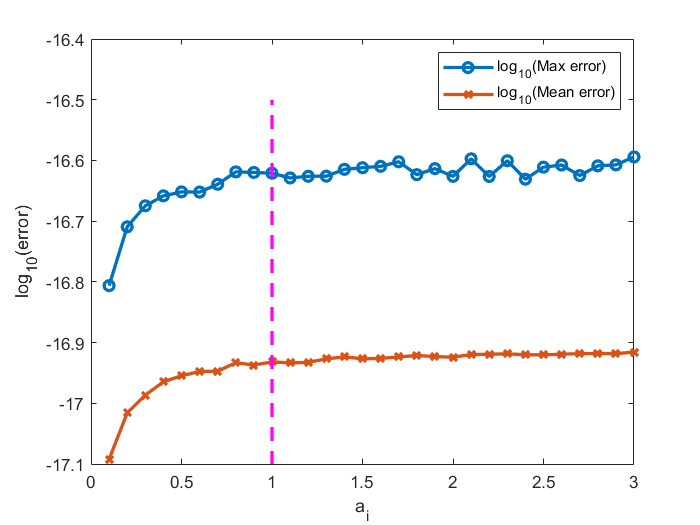

plot(a,MaxIerror,'-o',a,MeanIerror, '-x','linewidth', 2);
hold on
plot([1,1],ylim,'m--','linewidth', 2);
xlabel('a_i')
ylabel('log_{10}(error)')
legend('log_{10}(Max error)','log_{10}(Mean error)')
hold off

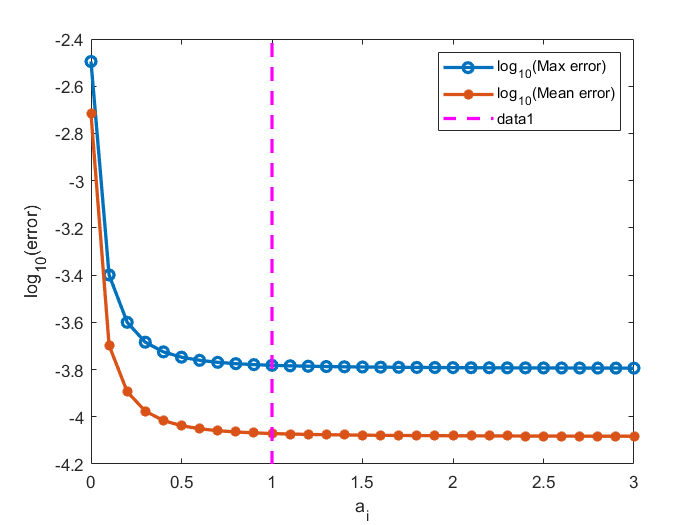

plot(a,Maxtesterror,'-o',a,Meantesterror, '-*','linewidth', 2);
xlabel('a_i')
ylabel('log_{10}(error)')
legend('log_{10}(Max error)','log_{10}(Mean error)')
hold on
plot([1,1],ylim,'m--','linewidth', 2);
hold off